## **Direct Kinematics**

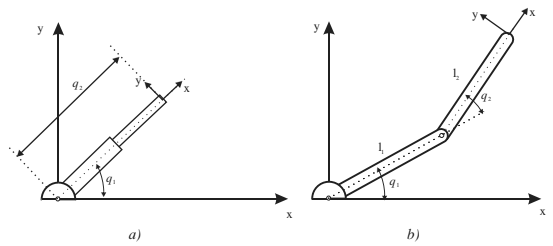

% With Geometric Method
syms q2 q1 l1 l2

% a)
x = q2 * cos(q1)

$$x = q_{2}\,\cos\left(q_{1}\right)$$

y = q2 * sin(q1)

$$y = q_{2}\,\sin\left(q_{1}\right)$$

z = 0;
noa = [cos(q1) -sin(q1) 0; sin(q1) cos(q1) 0; 0 0 1]

$$noa = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

% b)
x = l1 * cos(q1) + l2 * cos(q1 + q2)

$$x = l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)$$

y = l1 * sin(q1) + l2 * sin(q1 + q2)

$$y = l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)$$

z = 0;
noa = [cos(q1 + q2) -sin(q1 + q2) 0; sin(q1 + q2) cos(q1 + q2) 0; 0 0 1]

$$noa = \left(\begin{array}{ccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & 0\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

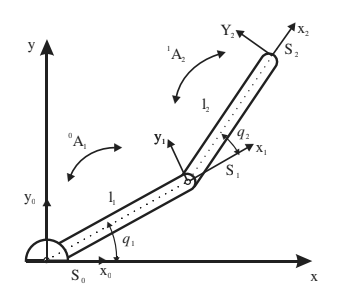

% With Homogeneous Transformation Matrixes
R = [cos(q1) -sin(q1) 0; sin(q1) cos(q1) 0; 0 0 1];
T1 = HTM(R);
p = [l1 0 0]';
T2 = HTM(eye(3), p);
A01 = T1 * T2

$$A01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & \bar{l_{1}}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & \bar{l_{1}}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R = [cos(q2) -sin(q2) 0; sin(q2) cos(q2) 0; 0 0 1];
T1 = HTM(R);
p = [l2 0 0]';
T2 = HTM(eye(3), p);
A12 = T1 * T2

$$A12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & \bar{l_{2}}\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & \bar{l_{2}}\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Ttotal = A01 * A12

$$Ttotal = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & \bar{l_{1}}\,\cos\left(q_{1}\right)+\bar{l_{2}}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\bar{l_{2}}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & \bar{l_{1}}\,\sin\left(q_{1}\right)+\bar{l_{2}}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\bar{l_{2}}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}=\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \sigma_{3}=\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) \end{array}$$

noa = Ttotal(1:3,1:3)

$$noa = \left(\begin{array}{ccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & 0\\ \cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

## Denavit Hartenberg Algorithm

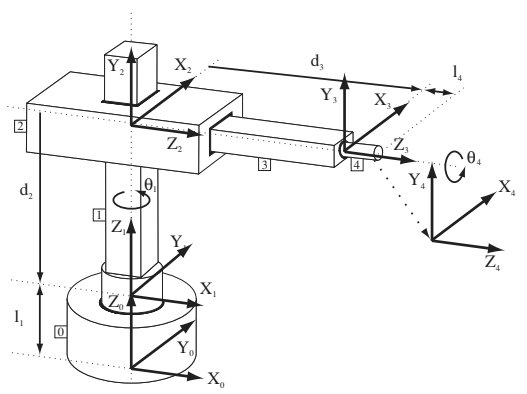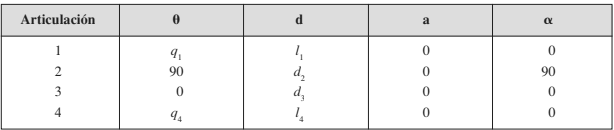

Where, 

- theta: means rotation in z axis

- d: means traslation in z axis

- a: means traslation in x axis

- alpha: means rotation in x axis

syms q1 l1 d2 d3 l4 q4

R = [cos(q1) -sin(q1) 0; sin(q1) cos(q1) 0; 0 0 1];
p = [0 0 l1]';
T1 = HTM(R);
T2 = HTM(eye(3), p);

A01 = T1 * T2

$$A01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & \bar{l_{1}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R1 = rotz(90);
p = [0 0 d2]';
R2 = rotx(90);

T1 = HTM(R1);
T2 = HTM(eye(3), p);
T3 = HTM(R2);

A12 = T1 * T2 * T3

$$A12 = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 1 & 0 & 0 & 0\\ 0 & 1 & 0 & \bar{d_{2}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

p = [0 0 d3]';
T1 = HTM(eye(3), p);

A23 = T1

$$A23 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \bar{d_{3}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R = [cos(q4) -sin(q4) 0; sin(q4) cos(q4) 0; 0 0 1];
p = [0 0 l4]';
T1 = HTM(R);
T2 = HTM(eye(3), p);

A34 = T1 * T2

$$A34 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & -\sin\left(q_{4}\right) & 0 & 0\\ \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & 0 & 0\\ 0 & 0 & 1 & \bar{l_{4}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Ttotal = A01 * A12 * A23 * A34

$$Ttotal = \left(\begin{array}{cccc} -\cos\left(q_{4}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{4}\right) & \cos\left(q_{1}\right) & \bar{l_{4}}\,\cos\left(q_{1}\right)+\bar{d_{3}}\,\cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\cos\left(q_{4}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{4}\right) & \sin\left(q_{1}\right) & \bar{d_{3}}\,\sin\left(q_{1}\right)+\bar{l_{4}}\,\sin\left(q_{1}\right)\\ \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & 0 & \bar{d_{2}}+\bar{l_{1}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

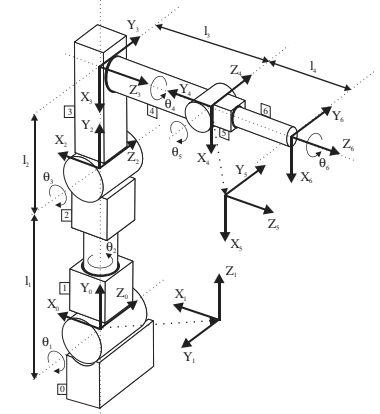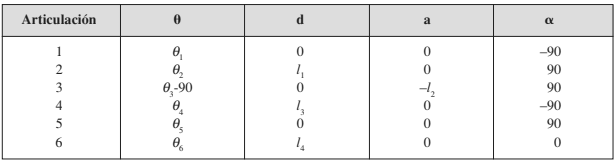

syms theta1 theta2 theta3 theta4 theta5 theta6 l1 l2 l3 l4

R1 = [cos(theta1) -sin(theta1) 0; sin(theta1) cos(theta1) 0; 0 0 1];
R2 = rotx(-90);
T1 = HTM(R1);
T2 = HTM(R2);

A01 = T1 * T2

$$A01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R1 = [cos(theta2) -sin(theta2) 0; sin(theta2) cos(theta2) 0; 0 0 1];
p = [0 0 l1]';
R2 = rotx(90);
T1 = HTM(R1);
T2 = HTM(eye(3), p);
T3 = HTM(R2);

A12 = T1 * T2 * T3

$$A12 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & 0 & \sin\left(\theta_{2}\right) & 0\\ \sin\left(\theta_{2}\right) & 0 & -\cos\left(\theta_{2}\right) & 0\\ 0 & 1 & 0 & \bar{l_{1}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R1 = [cos(theta3 - 90) -sin(theta3 - 90) 0; sin(theta3 - 90) cos(theta3 - 90) 0; 0 0 1];
p = [-l2 0 0]';
R2 = rotx(90);
T1 = HTM(R1);
T2 = HTM(eye(3), p);
T3 = HTM(R2);

A23 = T1 * T2 * T3

$$A23 = \left(\begin{array}{cccc} \cos\left(\theta_{3}-90\right) & 0 & \sin\left(\theta_{3}-90\right) & -\cos\left(\theta_{3}-90\right)\,\bar{l_{2}}\\ \sin\left(\theta_{3}-90\right) & 0 & -\cos\left(\theta_{3}-90\right) & -\sin\left(\theta_{3}-90\right)\,\bar{l_{2}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R1 = [cos(theta4) -sin(theta4) 0; sin(theta4) cos(theta4) 0; 0 0 1];
p = [0 0 l3]';
R2 = rotx(-90);
T1 = HTM(R1);
T2 = HTM(eye(3), p);
T3 = HTM(R2);

A34 = T1 * T2 * T3

$$A34 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & 0 & -\sin\left(\theta_{4}\right) & 0\\ \sin\left(\theta_{4}\right) & 0 & \cos\left(\theta_{4}\right) & 0\\ 0 & -1 & 0 & \bar{l_{3}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R1 = [cos(theta5) -sin(theta5) 0; sin(theta5) cos(theta5) 0; 0 0 1];
R2 = rotx(90);
T1 = HTM(R1);
T2 = HTM(R2);

A45 = T1 * T2

$$A45 = \left(\begin{array}{cccc} \cos\left(\theta_{5}\right) & 0 & \sin\left(\theta_{5}\right) & 0\\ \sin\left(\theta_{5}\right) & 0 & -\cos\left(\theta_{5}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R = [cos(theta6) -sin(theta6) 0; sin(theta6) cos(theta6) 0; 0 0 1];
p = [0 0 l4]';
T1 = HTM(R);
T2 = HTM(eye(3), p);

A56 = T1 * T2

$$A56 = \left(\begin{array}{cccc} \cos\left(\theta_{6}\right) & -\sin\left(\theta_{6}\right) & 0 & 0\\ \sin\left(\theta_{6}\right) & \cos\left(\theta_{6}\right) & 0 & 0\\ 0 & 0 & 1 & \bar{l_{4}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Ttotal = A01 * A12 *A23 * A34 * A45 * A56

% With Quaternions
